# Testing organic solids using SEPA standard default criteria

This guide explains how to aggregate the outputs in multiple sur files

## Reading in multiple sur files

We assume that we have a model run configured correctly and which has outputted the requisite solids sur files.

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project    = Depomod.Project.create(projectDir);

run = project.solidsRuns.number(3);

In order to read in multiple files we need the timestamps at which they were outputted. These can be retrieved easily using. 

t = run.outputTimestamps

t =     23760000    23770800    23781600    23792400    23803200    23814000    23824800    23835600    23846400    23857200    23868000    23878800    23889600    23900400    23911200    23922000    23932800    23943600    23954400    23965200    23976000    23986800    23997600    24008400    24019200    24030000    24040800    24051600    24062400    24073200    24084000    24094800    24105600    24116400    24127200    24138000    24148800    24159600    24170400    24181200    24192000    24202800    24213600    24224400    24235200    24246000    24256800    24267600    24278400    24289200


There are 720 sur files here representing 8 outputs per day for 90 days. 

Note that if the model was configured to output *more* than just the last 90 days then the list of output timestamps will include too many entries and will need to be curated in order to object just the ones needed. This might involve something like

%t = t(t > (365-90)*24*3600)

which would return only the timestamps in `t` that are within 90 days of the model endpoint (assuming no timestamps beyond 365 days).

In any case, once we have our list of timestamps we can read the respective sur files in. This may take a while.

surs = run.sur('type', 'solids', 'g', 0, 't', t)

surs = 1×720 cell array
  Columns 1 through 357
    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}

So we have a cell array of 720 sur files.

## Calculating the mean impact through time

We can average these surs through time using:

sur = surs{1}.clone;
surData = zeros(length(sur.Y), length(sur.X), numel(surs));

for i = 1:numel(surs)
    surData(:,:, i) = surs{i}.Z;
end

meanImpact = mean(surData,3);

sur.Z = squeeze(meanImpact); 
sur.interpolate;    

Now the sur variable has an average impact representation for the last 90 days. We can now analyse and plot this derived sur.

## Plotting the average impact

run.plot('sur', sur, 'levels', [1 250 1000]);

Let's also plot the 100 m mixing zone in order to provide context for what we'll measure next.

[x,y] = run.cages.cagePerimeter

x =           350420.278677024          350427.528628435          350434.721241987           350441.82813172          350448.821249988          350455.672998147          350462.356335478          350468.844885902          350475.113042074          350481.136066446          350486.890188892          350492.352700519          350497.502043291          350502.317895103          350506.781249988          350510.874493124          350514.581470351          350517.887551922          350520.779690244          350523.246471369          350525.278160038          350526.533384205          350527.118082142          350531.211325278          350534.918302505          350538.224384076          350541.116522398          350543.583303523          350545.614992192          350547.203570259           350548.34276833          350549.028090513          350549.256832154          350549.028090513           350548.34276833          350547.203570259          350545.614992192          350543.583303523        

y =           1069241.69125836          1069241.00593618           1069239.8667381          1069238.27816004          1069236.24647137          1069233.77969024          1069230.88755192          1069227.58147035          1069223.87449312          1069219.78124999           1069215.3178951          1069210.50204329          1069205.35270052          1069199.89018889          1069194.13606645          1069188.11304207           1069181.8448859          1069175.35633548          1069168.67299815          1069161.82124999          1069154.82813172           1069149.2125816          1069148.45879357          1069142.43576919          1069136.16761302           1069129.6790626          1069122.99572527          1069116.14397711          1069109.15085884          1069102.04396911          1069094.85135555          1069087.60140414          1069080.32272712           1069073.0440501          1069065.79409869          1069058.60148513           1069051.4945954          1069044.50147713        

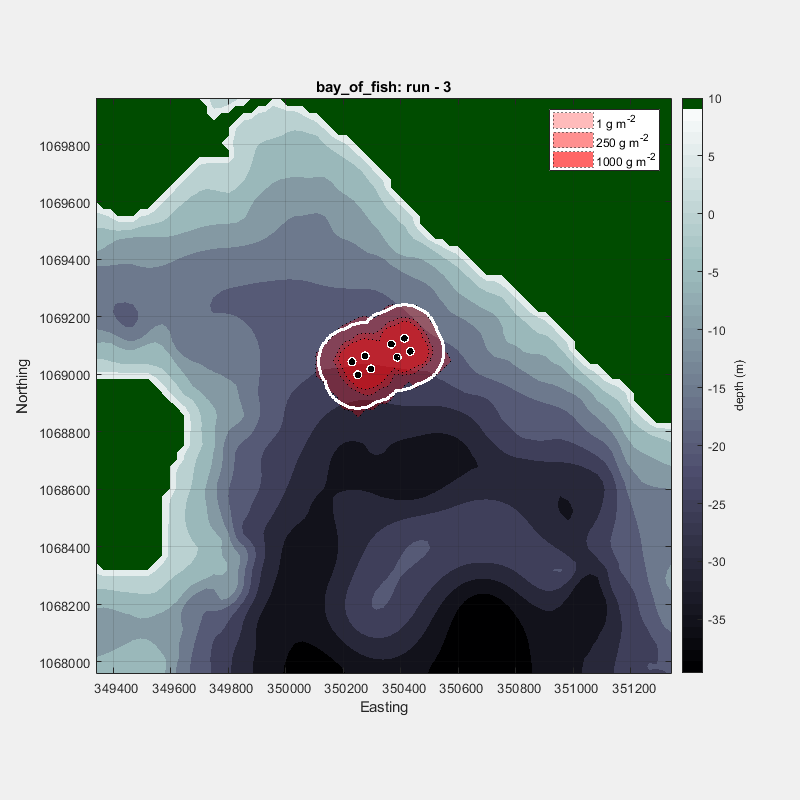

hold on
scatter3(x,y, repmat(15, numel(x),1),  'w.')

## Measuring the mixing zone impact extent

The *predicted* mixing zone impact area is measured as

sur.area(250)

ans =           58886.7626173552

and the *allowed *mixing zone area is

run.cages.compositeArea

ans =           109107.190649491

In this case, the predicted impact is around half of the allowed impact area. 

## Measuring the mixing zone impact intensity

Testing the overall intensity of the impact over this area

sur.mean(250)

ans =           6015.94329706676

This is greater than the 1000 g m-2 risk threshold and therefore this would be considered a risk for intensity impacts if no additional contextual information could be provided.